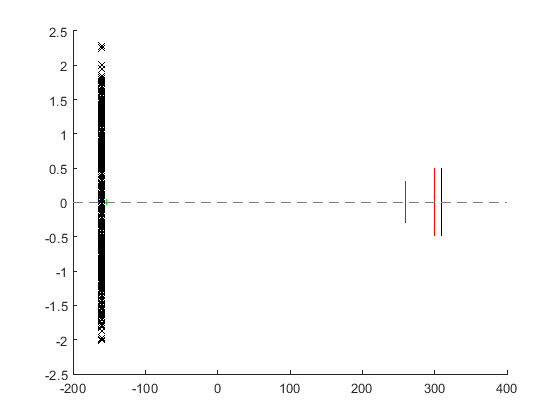

addpath("functionsAndGUI\")

%plot setup with no rays
beamon=false;

%Goebel specification
NRays=1E3; %number of rays per source
Ngoebel=1E4; %Number of sources on Goebel mirror

delta=0.03; %divergence angle
fwhm=1.35; %fwhm of Goebel source distr.
ds=160; %distance to sources on sarm
dgoebelsslit=7; %distance Goebel to source slit
gammas=90; %Goebel mirror rotation [deg] (90=not rotated)



%slit specifications
wsslit=0.1; %width source slit
wantisc=0.6; %width anti-scatter slit
wdslit=1; %width detector slit
dantisc=260; %distance antiscatter slit on darm
ddslit=300; %distance detector slit on darm

%detector speficications
dd=310;
wd=1;
NPixels=100;

%angles
alpha=45; %Source arm angle
beta=-45; %Detector arm angle





%items calculations
gammasslit=90; gammadslit=90; gammaantisc=90; gammad=90;
dsslit=ds-dgoebelsslit;

%Create setup
setup=startsetup();

setup=add_goebel(setup,ds,gammas,fwhm,Ngoebel,NRays,delta);
setup=add_sslit(setup,dsslit,wsslit, gammasslit);
setup=add_dslit(setup,dantisc,wantisc,gammaantisc);
setup=add_dslit(setup,ddslit,wdslit,gammadslit);
setup=add_detector(setup,dd,wd, gammad,NPixels);


%plot basic, non-rotated setup with beams off or on depending on beamon
fig1=plot_setup(setup,0,0,beamon,dd+1);

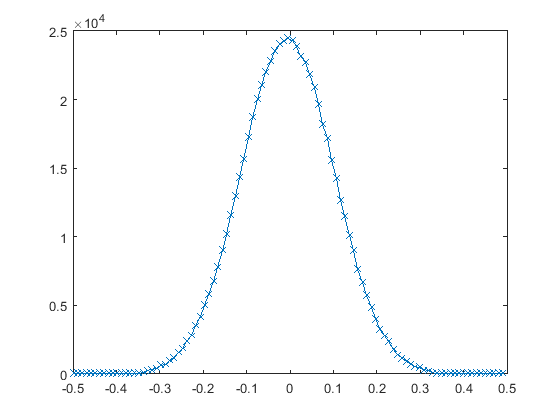


%Measure with detector 1
[a,I]=Scan_DetectorImage(setup,alpha,beta,1);


toc

Elapsed time is 4.150049 seconds.
